%% Random Forest Predictive Maintenance Model

clear
clc
close all

dataPath = "../data/datasets/ai4i2020.csv";

machineData = readtable(dataPath);


disp("Dataset loaded successfully")

Dataset loaded successfully


%% Feature Selection

featureNames = [ ...
    "AirTemperature_K_", ...
    "ProcessTemperature_K_", ...
    "RotationalSpeed_rpm_", ...
    "Torque_Nm_", ...
    "ToolWear_min_"];

X = machineData(:,featureNames);

Y = machineData.MachineFailure;

%% Split Dataset

rng(42)

cv = cvpartition(Y,"HoldOut",0.30);

XTrain = X(training(cv),:);
XTest = X(test(cv),:);

YTrain = Y(training(cv));
YTest = Y(test(cv));

fprintf("Training samples: %d\n",height(XTrain))

Training samples: 7000


fprintf("Testing samples: %d\n",height(XTest))

Testing samples: 3000


%% Train Random Forest Model

randomForestModel = fitcensemble( ...
    XTrain, ...
    YTrain, ...
    "Method","Bag", ...
    "NumLearningCycles",100, ...
    "Learners","Tree");

disp("Random Forest training complete")

Random Forest training complete


%% Save Random Forest Model

save("../models/randomForestModel.mat","randomForestModel")

disp("Random Forest model saved successfully")

Random Forest model saved successfully


%% Predictions

YPred_RF = predict(randomForestModel,XTest);

%% Accuracy

accuracy_RF = mean(YPred_RF == YTest)*100;

fprintf("Random Forest Accuracy: %.2f%%\n",accuracy_RF)

Random Forest Accuracy: 98.73%


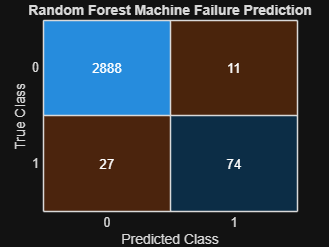

%% Confusion Matrix

figure

confusionchart(YTest,YPred_RF)

title("Random Forest Machine Failure Prediction")

%% Random Forest Performance Metrics

cm_RF = confusionmat(YTest,YPred_RF);

TN_RF = cm_RF(1,1);
FP_RF = cm_RF(1,2);
FN_RF = cm_RF(2,1);
TP_RF = cm_RF(2,2);

accuracy_RF = (TP_RF + TN_RF) / sum(cm_RF(:));

precision_RF = TP_RF / (TP_RF + FP_RF);

recall_RF = TP_RF / (TP_RF + FN_RF);

f1_RF = 2 * (precision_RF * recall_RF) / ...
    (precision_RF + recall_RF);

fprintf("Random Forest Results\n")

Random Forest Results


fprintf("---------------------\n")

---------------------


fprintf("Accuracy  : %.2f%%\n", accuracy_RF*100)

Accuracy  : 98.73%


fprintf("Precision : %.2f%%\n", precision_RF*100)

Precision : 87.06%


fprintf("Recall    : %.2f%%\n", recall_RF*100)

Recall    : 73.27%


fprintf("F1 Score  : %.2f%%\n", f1_RF*100)

F1 Score  : 79.57%


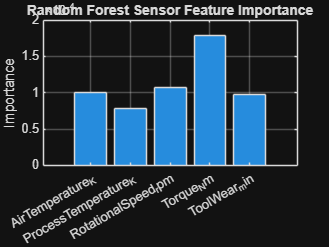

%% Random Forest Feature Importance

importance_RF = predictorImportance(randomForestModel);

figure

bar(importance_RF)

xticklabels(featureNames)

xtickangle(30)

ylabel("Importance")

title("Random Forest Sensor Feature Importance")

grid on